% syms r t psi t_0 v_x v_y
% 
% aa=R_mat(psi-r*t_0)*(A_mat(r*t)-A_mat(r*t_0))*[v_x;v_y]
% 
% simplify(aa)



## Polynomial curve fitting

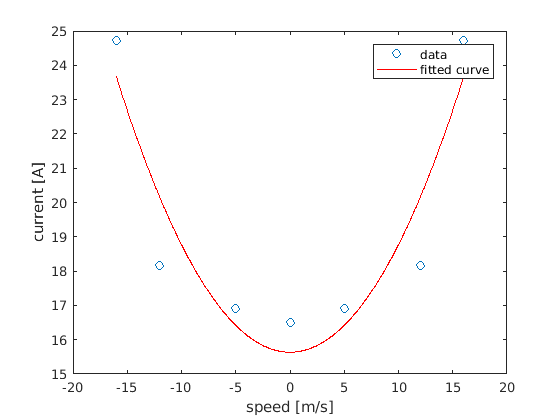

speed=[-16,-12,-5,0,5,12,16];
current=[24.73,18.17,16.9,16.5,16.9, 18.17, 24.73];

[pop2, gof]=fit(speed', current', 'poly2');
plot(pop2, speed, current ,'o')
xlabel('speed [m/s]');
ylabel('current [A]');

function A = A_mat(x)
    A=[sin(x), cos(x);-cos(x), sin(x)];
end

function R = R_mat(x)
    R=[cos(x), -sin(x);sin(x), cos(x)];
end

function p_n = dfsdf (t,t_0, psi_0,r,v_b,p_n_0)
    p_n = p_n_0 + R(psi_0-r*t_0)*(A(r*t)-A(r*t_0))*v_b;

    
end